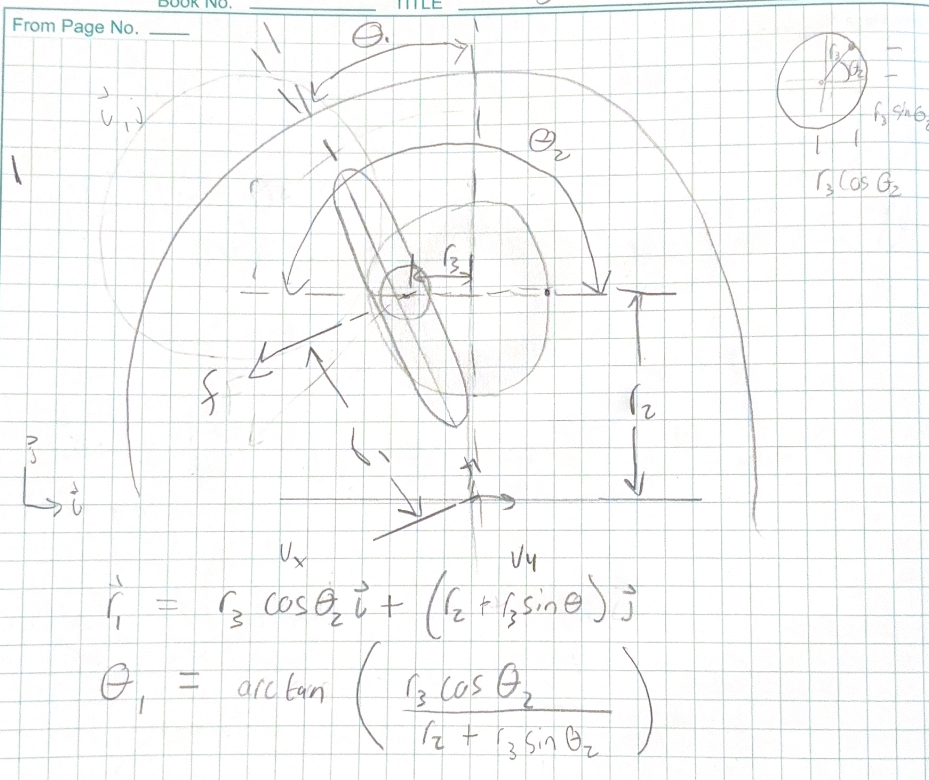

clc;
clear;
% note: theta 1 in drawing should stretch from r1 line to positive x axis
% motor speed, .5 Hz - full cycle is 25 degrees in 2 seconds
w = pi; %rad/s

% diameter, given
d = .718; %mm

% time vector, 0 to 10 seconds,1000 points
%t = linspace(0, 10, 1000); %s
t = linspace(0, 4, 1000); %s

%distance from central axes to center of motor plate
r2 = d/4; %mm

%required distance in 1 second
dis_deg = 12.5; %deg
dis_rad = 12.5*(2*pi)/360; %rad
dis_rad

dis_rad = 0.2182


%determine r3 with numerical analysis that yields +/- .2182 rads (12.5 deg)
for n=0:.0001:1
    [maxxy]=max(atan( (n * cos(w*t)) ./ (n * sin(w*t) + r2) ));
    if maxxy >= dis_rad/2
        disp(n)
        break
    
    end
end

    0.0196




r3 = n;
[maxxy2] = max(atan( (r3 * cos(w*t)) ./ (r3 * sin(w*t) + r2) ))

maxxy2 = 0.1094

maxxy_deg = maxxy2*360/(2*pi) %slightly over 12 degrees but close enough

maxxy_deg = 6.2687

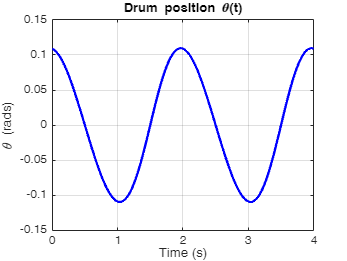

%could probably up the precision of the numerical analysis

%%% Angular position as a function of time


theta_t = atan( (r3 * cos(w*t)) ./ (r3 * sin(w*t) + r2) ); %angular position of drum, rads
%theta_t = atan( (r3 * cos(w*t)) ./ (r3 * sin(w*t) + r2) )*(360/(2*pi)); %angular position of drum, degrees

% Plot angular position of drum vs time
figure('WindowState', 'maximized');
plot(t, theta_t, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('\theta (rads)');
title('Drum position \theta(t)');
grid on;

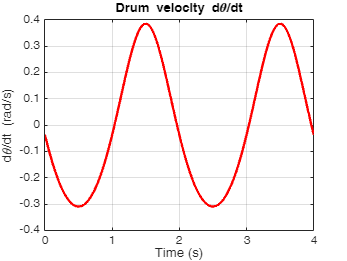


%%% Angular velocity as a function of time
%% Find derivative of angular position

% Compute f(t)
f_t = (r3 * cos(w*t)) ./ (r3 * sin(w*t) + r2);

% Compute f'(t) using the quotient rule
numerator = (-r3 * w .* sin(w*t)) .* (r3 * sin(w*t) + r2) - (r3 * w .* cos(w*t)) .* (r3 * cos(w*t));
denominator = (r3 * sin(w*t) + r2).^2;
f_derivative = numerator ./ denominator;

% Compute (1 + f^2(t))
one_plus_f2 = 1 + f_t.^2;

% Compute d(theta)/dt
dtheta_dt = f_derivative ./ one_plus_f2;

% Plot angular velocity of the drum vs time
figure('WindowState', 'maximized');
plot(t, dtheta_dt, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('d\theta/dt (rad/s)');
title('Drum velocity d\theta/dt');
grid on;

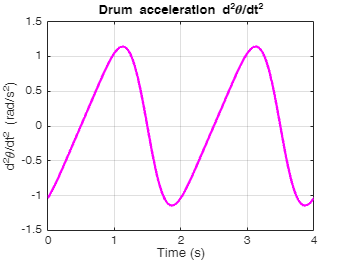


%%% Angular acceleration as a function of time
%% Find derivative of angular velocity
% % Compute f(t)
f_t = (r3 * cos(w*t)) ./ (r3 * sin(w*t) + r2);

% Compute f'(t) using the quotient rule
numerator_f1 = (-r3 * w .* sin(w*t)) .* (r3 * sin(w*t) + r2) - (r3 * w .* cos(w*t)) .* (r3 * cos(w*t));
denominator_f1 = (r3 * sin(w*t) + r2).^2;
f_derivative = numerator_f1 ./ denominator_f1;

% Compute (1 + f^2(t))
one_plus_f2 = 1 + f_t.^2;

% Compute d(theta)/dt
dtheta_dt = f_derivative ./ one_plus_f2;

% Compute f''(t) using numerical differentiation
dt = t(2) - t(1); % Time step
f_second_derivative = diff(f_derivative) / dt;
f_second_derivative = [f_second_derivative, f_second_derivative(end)]; % Maintain array size

% Compute d^2(theta)/dt^2
d2theta_dt2 = (f_second_derivative .* one_plus_f2 - 2 * f_t .* (f_derivative.^2)) ./ (one_plus_f2.^2);

% Plot acceleration as a function of time
figure('WindowState', 'maximized');
plot(t, d2theta_dt2, 'm', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('d^2\theta/dt^2 (rad/s^2)');
title('Drum acceleration d^2\theta/dt^2');
grid on;

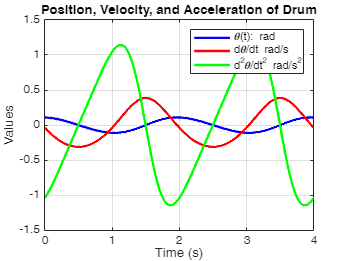


%%% Plot all results on top of each other
figure('WindowState', 'maximized');

% Plot theta(t)
plot(t, theta_t, 'b', 'LineWidth', 2);
hold on;  % Keep the plot active for the next plot

% Plot theta_dot(t) (first derivative)
plot(t, dtheta_dt, 'r', 'LineWidth', 2);

% Plot theta_double_dot(t) (second derivative)
plot(t, d2theta_dt2, 'g', 'LineWidth', 2);

% Add labels and grid
grid on;
xlabel('Time (s)');
ylabel('Values');
title('Position, Velocity, and Acceleration of Drum');
legend({'\theta(t): rad', 'd\theta/dt rad/s', 'd^2\theta/dt^2 rad/s^2'});
hold off;  % Release the plot hold

%%% Calculate Drum Torque
% Moment of Inertia about output coordinate system (true center, not center
% of mass % must this be reviewed? no, it is secured to rotate where the
% coordinate system is
I_z = 6949694.87; %g*cm^2
I_z = I_z*(10^-7); %kg*m^2
T = I_z*d2theta_dt2;
[T_max, t_max] = max(T) %max torque, time of max torque

T_max = 0.7933

t_max = 782

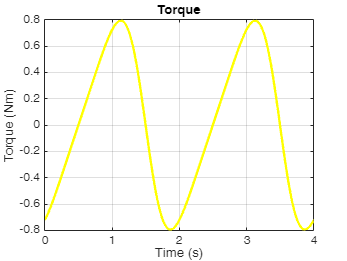


figure('WindowState', 'maximized');
plot(t, T, 'y', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Torque (Nm)');
title('Torque');
grid on;


% Calculate magnitude of moment arm that stretches from center of disk to
% force, perpindicular to force
rx = r3*cos(w*t_max) %m

rx = 0.0196

ry = r2 + r3*sin(w*t_max) %m

ry = 0.1795

r1 = sqrt((rx^2) + (ry^2)) %m

r1 = 0.1806

r2

r2 = 0.1795

r3

r3 = 0.0196

% max force exerted on to the drum
F_max = T_max/r1 %N

F_max = 4.3935


% max torque felt by the motor
T_mot_max = F_max*r3 %Nm

T_mot_max = 0.0861

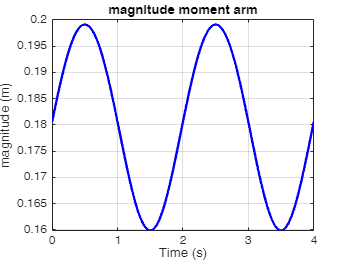


% can we turn this into a function? 
rx = r3*cos(w*t); %m
ry = r2 + r3*sin(w*t); %m
r1 = sqrt((rx.^2) + (ry.^2)); %m

figure('WindowState', 'maximized');
plot(t, r1, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('magnitude (m)');
title('magnitude moment arm');
grid on;

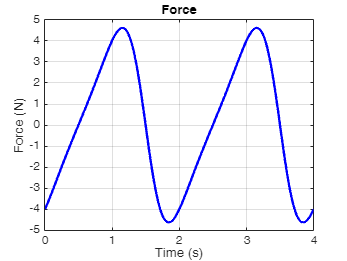


F = T./r1;

figure('WindowState', 'maximized');
plot(t, F, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Force (N)');
title('Force');
grid on;



%%% ANSWER
[Fmax,tmax] = max(F)

Fmax = 4.6118

tmax = 289

T_mot_max = Fmax*r3 %Nm

T_mot_max = 0.0904

F(t_max)*r1(tmax)

ans = 0.7864


%T_motor = F*r3
T_motor = F.*r3.*sin(w*t)

T_motor =          0   -0.0010   -0.0019   -0.0029   -0.0038   -0.0047   -0.0056   -0.0065   -0.0074   -0.0083   -0.0091   -0.0099   -0.0107   -0.0115   -0.0123   -0.0130   -0.0138   -0.0145   -0.0152   -0.0159   -0.0165   -0.0172   -0.0178   -0.0184   -0.0190   -0.0195   -0.0201   -0.0206   -0.0211   -0.0216   -0.0221   -0.0225   -0.0230   -0.0234   -0.0238   -0.0241   -0.0245   -0.0248   -0.0251   -0.0254   -0.0257   -0.0260   -0.0262   -0.0264   -0.0267   -0.0268   -0.0270   -0.0272   -0.0273   -0.0274


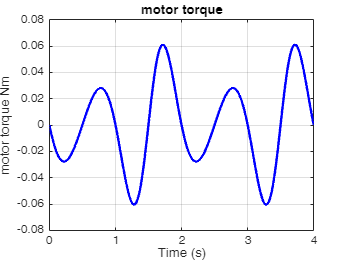



figure('WindowState', 'maximized');
plot(t, T_motor, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('motor torque Nm');
title('motor torque');
grid on;


%try 2 
%motor_moment_arm
theta3 = 360-90-theta_t;
theta4 = 270-theta3;
theta5 = 90-theta4-(180-(w*t));
z = r3*cos(theta5);

Mot_torque = F.*z

Mot_torque =     0.0424    0.0413    0.0402    0.0391    0.0379    0.0368    0.0357    0.0346    0.0335    0.0323    0.0312    0.0301    0.0291    0.0280    0.0269    0.0258    0.0248    0.0237    0.0227    0.0216    0.0206    0.0196    0.0186    0.0176    0.0166    0.0156    0.0147    0.0137    0.0128    0.0119    0.0110    0.0101    0.0092    0.0084    0.0075    0.0067    0.0059    0.0051    0.0043    0.0035    0.0028    0.0020    0.0013    0.0006   -0.0001   -0.0007   -0.0014   -0.0020   -0.0026   -0.0032


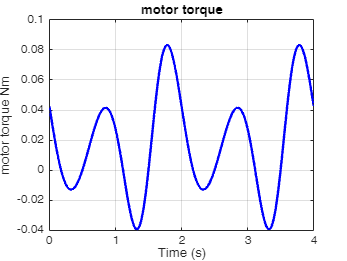

figure('WindowState', 'maximized');
plot(t, Mot_torque, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('motor torque Nm');
title('motor torque');
grid on;


[max_motor_torque,raddy] = max(Mot_torque)

max_motor_torque = 0.0832

raddy = 446